***Wireless Communications EL-GY 6023***

Homework 3 - Tommy Azzino (ta1731)

Problem 2 

(c )

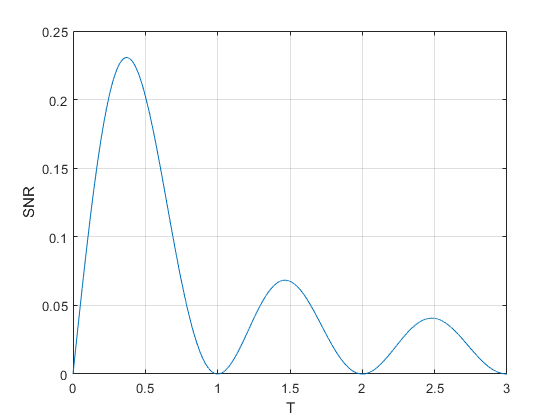

npoints = 10000;
t_values = linspace(0,3,npoints);
p_N0 = 1;
f_offset = 1;
f_snr = @(t,f_off,p_0) sinc(f_off*t).^2.*t*p_0;
snr = f_snr(t_values,f_offset,p_N0);
plot(t_values,snr); grid on;
xlabel("T"); ylabel("SNR");

[snr_max, idx_max] = max(snr);
Tmax = t_values(idx_max);
fprintf(1, 'max snr = %.2f\n', snr_max);

max snr = 0.23


fprintf(1, 'optimal integration time = %f\n', Tmax);

optimal integration time = 0.371137



% Expression to evaluate other values for P/N0 and (offset) f;
f_snr_max = @(f_offest,p_N0) sinc(f_offset*Tmax)^2*Tmax*p_N0;

(d)

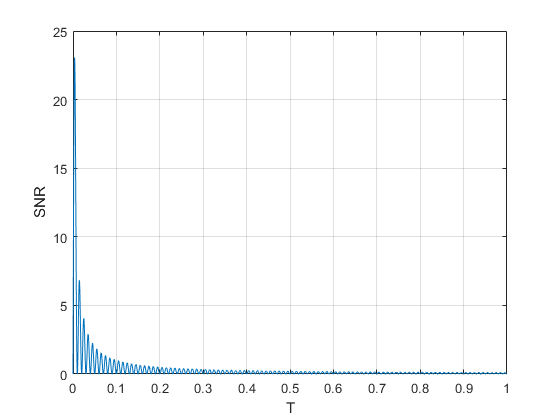

t_values = linspace(0,1,npoints);
P = -100; % dBm
Plin = db2pow(P-30); % convert to dBW, then to linear
N0 = -140;
N0lin = db2pow(N0-30);
P_overN0 = Plin/N0lin;
new_offset = 100;
snr_2 = f_snr(t_values,new_offset,P_overN0);
plot(t_values,snr_2); grid on;
xlabel("T"); ylabel("SNR");


[snr_max2, idx_max2] = max(snr_2);
Tmax2 = t_values(idx_max2);
fprintf(1, 'max snr = %.2f\n', snr_max2);

max snr = 23.06


fprintf(1, 'max snr [dB] = %.2f\n', pow2db(snr_max2));

max snr [dB] = 13.63


fprintf(1, 'optimal integration time [ms] = %f\n', Tmax2*1e3);

optimal integration time [ms] = 3.700370


Problem 3

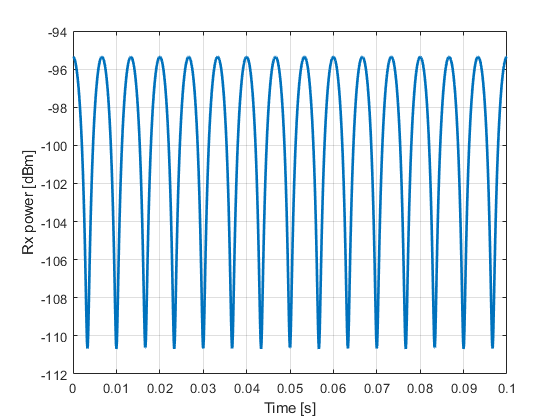

RxP = [-100, -103];
RxPlin = db2pow(RxP-30);
dopp = [100, -50];
t = linspace(0,0.1,1000)';
phase = 2*pi*t*dopp;
gaindB = [0,-3];

hpow = db2pow(gaindB);
h = sqrt(hpow);

H = exp(1i*phase).*h;
Pow_t = -100+ 10*log10(abs(sum(H,2)).^2);
figure;
plot(t,Pow_t,'LineWidth',2); grid on;
xlabel("Time [s]"); ylabel("Rx power [dBm]") 

fprintf(1, 'max rx power [dBm] = %.2f\n', max(Pow_t));

max rx power [dBm] = -95.35


fprintf(1, 'min rx power [dBm] = %.2f\n', min(Pow_t));

min rx power [dBm] = -110.69


[min_v,idx] = min(Pow_t);
t_min = t(Pow_t < min_v+1);
fprintf(1, 'tmin [s] = %f\n', t_min(1));

tmin [s] = 0.003203


fprintf(1, 'avg power [dBm] = %.2f\n', mean(Pow_t));

avg power [dBm] = -100.00


frac = sum(Pow_t >= -101)/length(Pow_t);
fprintf(1, 'frac power > -101 dBm = %f\n', frac*100);

frac power > -101 dBm = 66.400000


Problem 4

(b) and (c )

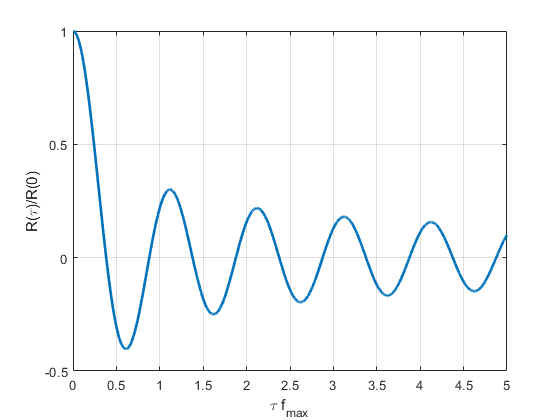

npoints = 10000;
tau_fmax = linspace(0,5,npoints);
R_tau_over_0 = besselj(0,tau_fmax*2*pi);
figure;
plot(tau_fmax, R_tau_over_0, "LineWidth", 2);
grid on; xlabel('\tau f_{max}'); ylabel('R(\tau)/R(0)');

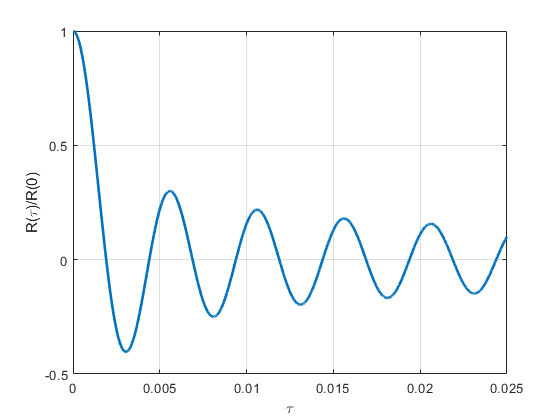


figure;
fmax = 200;
J0 = besselj(0,-tau_fmax*2*pi);
plot(tau_fmax/fmax, J0, "LineWidth",2);
grid on; xlabel('\tau'); ylabel('R(\tau)/R(0)');


tau = tau_fmax/fmax;
tau_v = tau(J0 >= 0.95);
fprintf(1, 'time it takes for the channel to change 10 perc [us] = %f\n', tau_v(end)*1e6);

time it takes for the channel to change 10 perc [us] = 357.535754
